 %%%%% .
clc
clear all
close all

%%%%%%%%%% Experimental data 10,0

%%%%%%
Srate = [1 0.75 0.5 0.25]'*1e-3 ;
Sut_100= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\Sut_100.txt','r');
Sut_200= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\Sut_200.txt','r');
Sut_MWCNT =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\Sut_MWCNT.txt','r');

Sut100 = [cell2mat(textscan(Sut_100,'%f%f%f%f'))] %strain

Sut100 =    77.3001   48.4784   29.4754   21.2166
   77.0019   48.1630   30.5163   18.8230
   77.7059   47.8081   30.8004   20.4500
   77.2104   45.9314   28.1527   16.0532


Sut200 = [cell2mat(textscan(Sut_200,'%f%f%f%f'))]     %300K,800k,1600k,2400k

Sut200 =    55.6327   40.5997   24.0119   18.7240
   55.0637   41.0658   25.3496   18.9789
   55.3495   40.5740   26.4597   18.7657
   55.1348   40.0446   21.3012   18.4414


Sutmwcnt = [cell2mat(textscan(Sut_MWCNT,'%f%f%f%f'))]    %in

Sutmwcnt =    57.1540   42.5519   31.2346   33.2784
   56.2304   40.2576   32.8403   30.2103
   55.1935   41.1430   31.7816   30.7699
   56.4583   40.1597   32.4106   28.9946


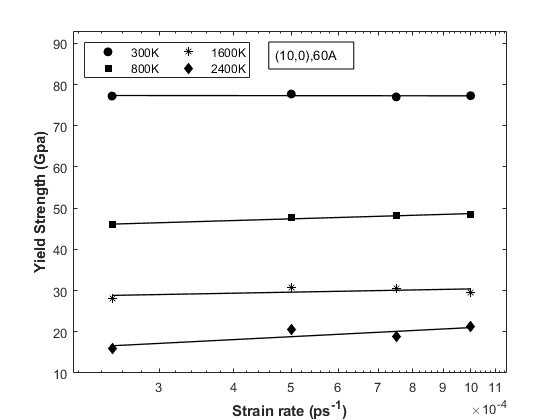

fclose(Sut_200);fclose(Sut_MWCNT);fclose(Sut_100);

C1_300K= Sut100(1:4,1);
C1_800K= Sut100(1:4,2);
C1_1600K= Sut100(1:4,3);
C1_2400K= Sut100(1:4,4);
C2_300K= Sut200(1:4,1);
C2_800K= Sut200(1:4,2);
C2_1600K= Sut200(1:4,3);
C2_2400K= Sut200(1:4,4);
MW_300K= Sutmwcnt(1:4,1);
MW_800K= Sutmwcnt(1:4,2);
MW_1600K= Sutmwcnt(1:4,3);
MW_2400K= Sutmwcnt(1:4,4);

%scnt 10,0 simulation
% C1_300K = [0.196 0.20 0.189 0.194]'   ;    %YIELD STRAIN
% C1_800K=[0.16 0.176 0.171 0.167]';
% C1_1600K=[0.127 0.1334 0.1375 0.1214 ]';
% C1_2400K=[0.1099 0.105 0.101 0.073]';


f1 = polyfit(log(Srate),C1_300K,1); fitf1=polyval(f1,log(Srate));
f2 = polyfit(log(Srate),C1_800K,1); fitf2=polyval(f2,log(Srate));
f3 = polyfit(log(Srate),C1_1600K,1); fitf3=polyval(f3,log(Srate));
f4 = polyfit(log(Srate),C1_2400K,1); fitf4=polyval(f4,log(Srate));

figure(1)%%%%%
semilogx(Srate,C1_300K,'ok',"MarkerFaceColor","k"); hold on %%%simulat
semilogx(Srate,C1_800K,'sk',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_1600K,'*k',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_2400K,'dk',"MarkerFaceColor","k"); hold on

semilogx(Srate,fitf1,'-k','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2,'-k','LineWidth',1); hold on
semilogx(Srate,fitf3,'-k','LineWidth',1); hold on
semilogx(Srate,fitf4,'-k','LineWidth',1); hold on



% semilogx(ExpSr300K,ExpYs300K,'ob',"MarkerFaceColor","b"); hold on  % experimental data 10,0
% semilogx(ExpSr800K,ExpYs800K,'sb',"MarkerFaceColor","b"); hold on
% semilogx(ExpSr1600K,ExpYs1600K,'*b',"MarkerFaceColor","b"); hold on
% semilogx(ExpSr2400K,ExpYs2400K,'db',"MarkerFaceColor","b"); hold on

xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Yield Strength (Gpa)',"FontWeight","bold")

lgd= legend('300K','800K','1600K','2400K','','','','','Location','northwest','NumColumns',2);
% title(lgd,'MD           Literature') 
xlim([0.000215 0.001151])
ylim([10 93])


annotation('textbox', [0.48, 0.8, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Syt_vs_Srate10060A.jpg')

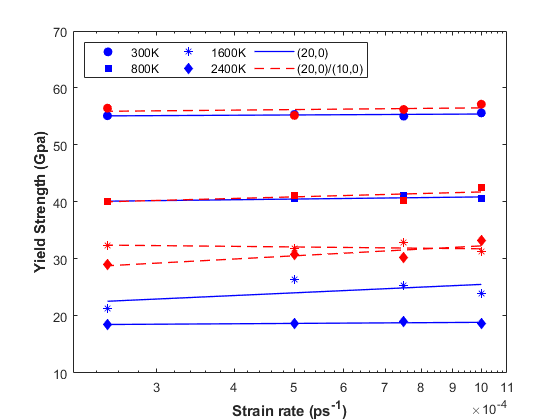

%%%%% cnt.20.0.60

%strain at temp 20,0,60
% C2_300K = [0.21 0.208 0.206 0.20]'   ;    %YIELD STRAIN
% C2_800K=[.1899 .189 .182 .18]';
% C2_1600K=[.1258 .131 .1415 .106]';
% C2_2400K=[.1095 .109 .1057 .09]';
% Srate = [1 0.75 0.5 0.25]'*1e-3 ;   
% %55swcnt20,0
f1h = polyfit(log(Srate),C2_300K,1); fitf1h=polyval(f1h,log(Srate));
f2h= polyfit(log(Srate),C2_800K,1); fitf2h=polyval(f2h,log(Srate));
f3h= polyfit(log(Srate),C2_1600K,1); fitf3h=polyval(f3h,log(Srate));
f4h= polyfit(log(Srate),C2_2400K,1); fitf4h=polyval(f4h,log(Srate));

%Mwcnt
% MW_300K = [.1858 .1847 .1789 .1858]'   ;    %YIELD STRAIN
% MW_800K=[.1609 .1537 .1564 .155]';
% MW_1600K=[.19 .198 .194 .195]';
% MW_2400K=[.18 .185 .183 .180]';
% %mwcnt....
f1m = polyfit(log(Srate),MW_300K,1); fitf1m=polyval(f1m,log(Srate));
f2m= polyfit(log(Srate),MW_800K,1); fitf2m=polyval(f2m,log(Srate));
f3m= polyfit(log(Srate),MW_1600K,1); fitf3m=polyval(f3m,log(Srate));
f4m= polyfit(log(Srate),MW_2400K,1); fitf4m=polyval(f4m,log(Srate));

%%% comparision  20,0 vs 20,0/10,0
figure(2)
semilogx(Srate,C2_300K,'ob',"MarkerFaceColor","b"); hold on %%%simulat
semilogx(Srate,C2_800K,'sb',"MarkerFaceColor","b"); hold on
semilogx(Srate,C2_1600K,'*b',"MarkerFaceColor","b"); hold on
semilogx(Srate,C2_2400K,'db',"MarkerFaceColor","b"); hold on

semilogx(Srate,fitf1h,'-b','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2h,'-b','LineWidth',1); hold on
semilogx(Srate,fitf3h,'-b','LineWidth',1); hold on
semilogx(Srate,fitf4h,'-b','LineWidth',1); hold on

semilogx(Srate,MW_300K,'or',"MarkerFaceColor","r"); hold on %%%simulat
semilogx(Srate,MW_800K,'sr',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_1600K,'*r',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_2400K,'dr',"MarkerFaceColor","r"); hold on

semilogx(Srate,fitf1m,'--r','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf3m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf4m,'--r','LineWidth',1); hold on

xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Yield Strength (Gpa)',"FontWeight","bold")


lgd= legend('300K','800K','1600K','2400K','','(20,0)','','','','','','','','(20,0)/(10,0)','','','Location','northwest','NumColumns',3);
%title(lgd,'(20,0)       (20,0)/(10,0)') 
xlim([0.00022  0.0011])
 ylim([10 70])
%annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Syt_vs_Srate_Comparison.jpg')

hold off

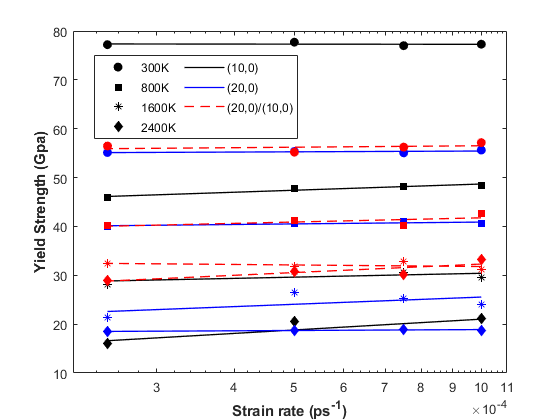

%%% all in one
figure(3)
semilogx(Srate,C1_300K,'ok',"MarkerFaceColor","k"); hold on %%%simulat
semilogx(Srate,C1_800K,'sk',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_1600K,'*k',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_2400K,'dk',"MarkerFaceColor","k"); hold on

semilogx(Srate,fitf1,'-k','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2,'-k','LineWidth',1); hold on
semilogx(Srate,fitf3,'-k','LineWidth',1); hold on
semilogx(Srate,fitf4,'-k','LineWidth',1); hold on

semilogx(Srate,C2_300K,'ob',"MarkerFaceColor","b"); hold on %%%simulat
semilogx(Srate,C2_800K,'sb',"MarkerFaceColor","b"); hold on
semilogx(Srate,C2_1600K,'*b',"MarkerFaceColor","b"); hold on
semilogx(Srate,C2_2400K,'db',"MarkerFaceColor","b"); hold on

semilogx(Srate,fitf1h,'-b','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2h,'-b','LineWidth',1); hold on
semilogx(Srate,fitf3h,'-b','LineWidth',1); hold on
semilogx(Srate,fitf4h,'-b','LineWidth',1); hold on

semilogx(Srate,MW_300K,'or',"MarkerFaceColor","r"); hold on %%%simulat
semilogx(Srate,MW_800K,'sr',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_1600K,'*r',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_2400K,'dr',"MarkerFaceColor","r"); hold on

semilogx(Srate,fitf1m,'--r','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf3m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf4m,'--r','LineWidth',1); hold on

xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Yield Strength (Gpa)',"FontWeight","bold")


lgd= legend('300K','800K','1600K','2400K','','(10,0)','','','','','','','','(20,0)','','','','','','','','(20,0)/(10,0)','','','Position',[0.3 0.67 0.1 0.2],'NumColumns',2);
%title(lgd,'(20,0)       (20,0)/(10,0)') 
xlim([0.00022  0.0011])
 ylim([10 80])
%annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Syt_vs_Srate_ComapaAll.jpg')

hold off